## **II/ Génération d'un signal sinusoïdal**

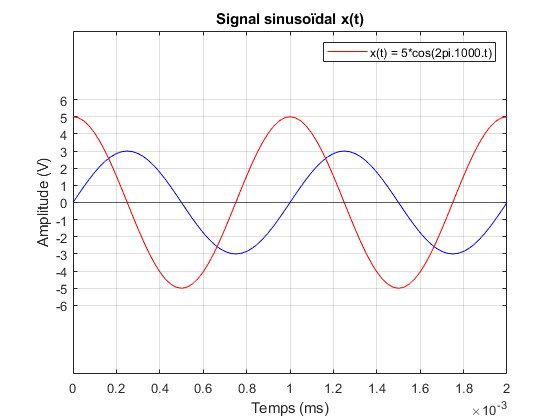

clc;
close; %ferme les anciennes figures
clear; %efface l'ancien workspace


f = 1000; %fréquence signal sinuisoïdal
A = 5; %amplitude de la sinusoïde

fe = 40000; %fréquence échantillonnage
Te=1/fe; %durée échantillon
Ns=2000; %nombre échantillon

t = 0:Te:(Ns-1)*Te;

x=A*cos(2*pi*f*t);
y=3*sin(2*pi*f*t);

plot(t,x,"r"); %trace le signal x(t) en rouge
title("Signal sinusoïdal x(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
xlabel("Temps (ms)");
legend("x(t) = 5*cos(2pi.1000.t)");
axis([0 2*1e-3 -10 10]); % règle les axes
grid on;

Calcul nombres de périodes:

duree = Ns*Te

duree = 0.0500

T = 1/f

T = 1.0000e-03

NbrPeriode = duree/T

NbrPeriode = 50

## **III/ Affichage du signal x(t)**

1. Signaux affichés avec la fonction subplot

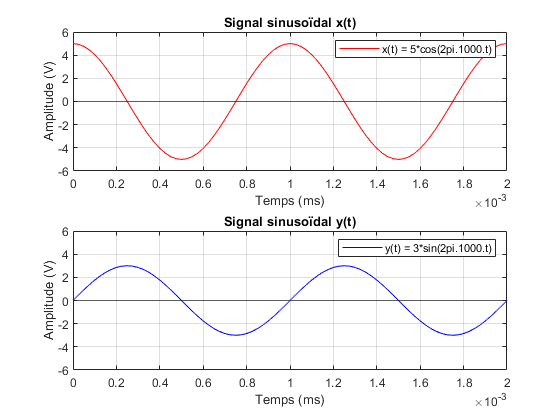

figure;
subplot(2,1,1);
plot(t,x,"r"); %trace le signal x(t) en rouge
title("Signal sinusoïdal x(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("Temps (ms)");
yticks(-6:2:6); %permet de régler l'échelle verticale
xticks(0:0.2*1e-3:2*1e-3); %permet de régler l'échelle horizontale
legend("x(t) = 5*cos(2pi.1000.t)");
axis([0 2*1e-3 -6 6]); % règle les axes
grid on;

subplot(2,1,2)
plot(t,y,"b"); %trace le signal y(t) en bleu
title("Signal sinusoïdal y(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("Temps (ms)");
legend("y(t) = 3*sin(2pi.1000.t)"); %défini une légende
yticks(-6:2:6); %permet de régler l'échelle verticale
xticks(0:0.2*1e-3:2*1e-3); %permet de régler l'échelle horizontale
axis([0 2*1e-3 -6 6]); % règle les axes
grid on; % affiche une grille

2. Signaux affichés sur le même graphe

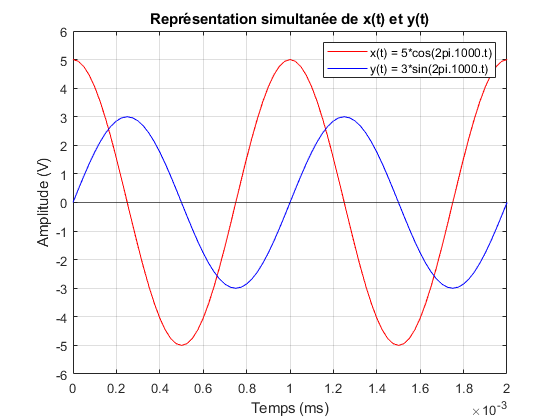

figure;
plot(t,x,"r"); %trace le signal x(t) en rouge

hold on;

plot(t,y,"b"); %trace le signal y(t) en bleu

title("Représentation simultanée de x(t) et y(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("Temps (ms)");
legend("x(t) = 5*cos(2pi.1000.t)","y(t) = 3*sin(2pi.1000.t)"); %défini une légende
yticks(-6:1:6); %permet de régler l'échelle verticale
xticks(0:0.2*1e-3:2*1e-3); %permet de régler l'échelle horizontale
axis([0 2*1e-3 -6 6]); % règle les axes
grid on; % affiche une grille

## **V/ Affichage du spectre**

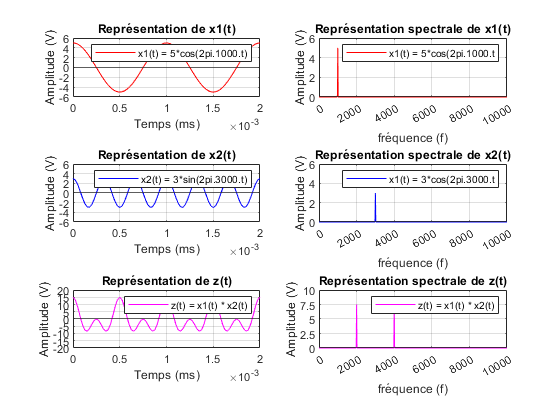


A1=5;
f1=1000;
A2=3;
f2=3000;

% génération de x1(t)
x1=A1*cos(2*pi*f1*t);

% génération de x2(t)
x2=A2*cos(2*pi*f2*t);

figure;
subplot(3,2,1) 
plot(t,x1,"r"); %trace le signal x1(t) en rouge
title("Représentation de x1(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("Temps (ms)");
legend("x1(t) = 5*cos(2pi.1000.t)"); %défini une légende
yticks(-6:2:6); %permet de régler l'échelle verticale
xticks(0:0.5*1e-3:2*1e-3); %permet de régler l'échelle horizontale
axis([0 2*1e-3 -6 6]); % règle les axes
grid on; % affiche une grille

subplot(3,2,3)
plot(t,x2,"b"); %trace le signal x2(t) en bleu
title("Représentation de x2(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("Temps (ms)");
legend("x2(t) = 3*sin(2pi.3000.t)"); %défini une légende
yticks(-6:2:6); %permet de régler l'échelle verticale
xticks(0:0.5*1e-3:2*1e-3); %permet de régler l'échelle horizontale
axis([0 2*1e-3 -6 6]); % règle les axes
grid on; % affiche une grille

z = x1 .* x2;

subplot(3,2,5)
plot(t,z,"m"); %trace le signal y(t) en bleu
title("Représentation de z(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("Temps (ms)");
legend("z(t) = x1(t) * x2(t)"); %défini une légende
yticks(-20:5:20); %permet de régler l'échelle verticale
xticks(0:0.5*1e-3:2*1e-3); %permet de régler l'échelle horizontale
axis([0 2*1e-3 -20 20]); % règle les axes
grid on; % affiche une grille


[X1 F]=spectre(x1,fe,Ns);

subplot(3,2,2);
plot(F,X1,"r");
title("Représentation spectrale de x1(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("fréquence (f)");
legend("x1(t) = 5*cos(2pi.1000.t"); %défini une légende
yticks(0:2:6); %permet de régler l'échelle verticale
xticks(0:0.2*1e4:1*1e4); %permet de régler l'échelle horizontale
axis([0 1*1e4 0 6]); % règle les axes
grid on; % affiche une grille

[X2 F]=spectre(x2,fe,Ns);

subplot(3,2,4);
plot(F,X2,"b");
title("Représentation spectrale de x2(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("fréquence (f)");
legend("x1(t) = 3*cos(2pi.3000.t"); %défini une légende
yticks(0:2:6); %permet de régler l'échelle verticale
xticks(0:0.2*1e4:1*1e4); %permet de régler l'échelle horizontale
axis([0 1*1e4 0 6]); % règle les axes
grid on; % affiche une grille

[Z, F]=spectre(z,fe,Ns);

subplot(3,2,6);
plot(F,Z,"m");
title("Représentation spectrale de z(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
yline(0); %met une ligne à 0
xlabel("fréquence (f)");
legend("z(t) = x1(t) * x2(t)"); %défini une légende
yticks(0:2.5:10); %permet de régler l'échelle verticale
xticks(0:0.2*1e4:1*1e4); %permet de régler l'échelle horizontale
axis([0 1*1e4 0 10]); % règle les axes
grid on; % affiche une grille